# Laboratorium 5

Karolina Piotrowska

### Zadanie 1

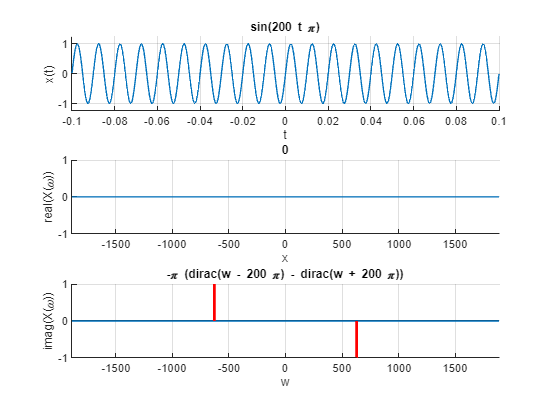

syms t x f0 w w0 X_FT
f0 = 100;
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2)];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = sin(w0*t);
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

### ZD1

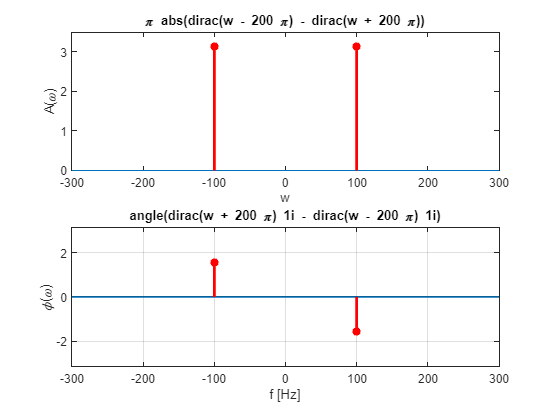

clear all;
close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = sin(w0*t);
X_FT = fourier(x);
A = abs(X_FT); % gestosc widmowa mocy
fi = angle(X_FT);
commentA = 0;
commentFi = 0;
figure;
subplot(2,1,1);
ezplot(A,BND_w/2/pi);
hold on;
v_num = subs(A,w,w_SMP);
n = find(abs(v_num) == inf); % plot dirac(inf)
stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
ylabel('A(\omega)');
ylim([-0.001 3.5]);
subplot(2,1,2);
ezplot(fi,(BND_w/2/pi)');
hold on;
grid on;
v_num = subs(fi,w,w_SMP);
n = find(abs(v_num) == inf); % plot dirac(inf)
stem(w_SMP(n)/2/pi, pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
stem(-100, pi/2, 'r*', 'LineWidth', 2);
stem(100, -pi/2, 'r*', 'LineWidth', 2);
ylim([-pi pi]);
xlabel('f [Hz]');
ylabel('\phi(\omega)');

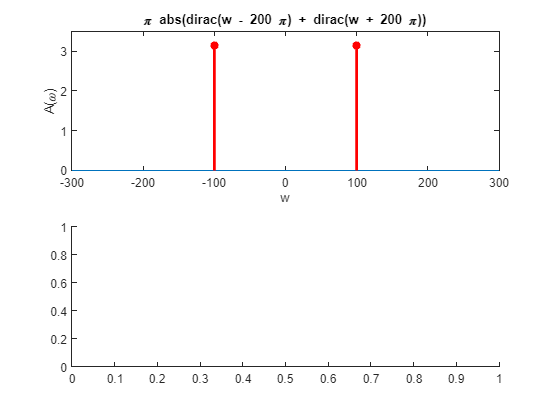

clear all;
close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = cos(w0*t);
X_FT = fourier(x);
A = abs(X_FT); % gestosc widmowa mocy
fi = angle(X_FT);
commentA = 0;
commentFi = 0;
figure;
subplot(2,1,1);
ezplot(A,BND_w/2/pi);
hold on;
v_num = subs(A,w,w_SMP);
n = find(abs(v_num) == inf); % plot dirac(inf)
stem(w_SMP(n)/2/pi,pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
ylabel('A(\omega)');
ylim([-0.001 3.5]);
subplot(2,1,2);

ezplot(fi,(BND_w/2/pi)');

Error using ezplot>ezplot1
The input character vector must be an expression.  Implicit functions of a single variable are not supported.

Error in ezplot (line 153)
                [hp, cax] = ezplot1(cax, f{1}, vars, labels, args{:});

Error in sym/ezplot (line 78)
      h = ezplo

hold on;
grid on;
v_num = subs(fi,w,w_SMP);
n = find(abs(v_num) == inf); % plot dirac(inf)
stem(w_SMP(n)/2/pi, pi*sign(v_num(n)), 'r*', 'LineWidth', 2);
stem(-100, pi/2, 'r*', 'LineWidth', 2);
stem(100, -pi/2, 'r*', 'LineWidth', 2);
ylim([-pi pi]);
xlabel('f [Hz]');
ylabel('\phi(\omega)');

Gęstość widmowa amplitudy jest taka sama dla sinusa i cosinusa. 

### Zadanie 2

cos(omega t)

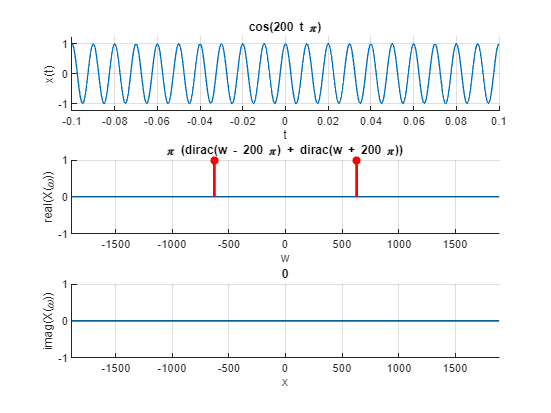

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = cos(w0*t);
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

Sygnałstały o wartości 10

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = sym(10)

$$x = 10$$

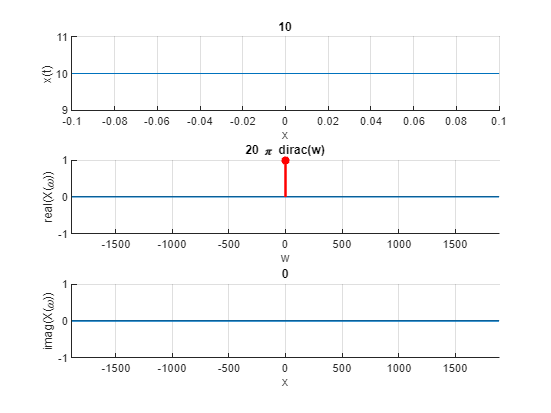

X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

Skok jednostkowy o amplitudzie 1

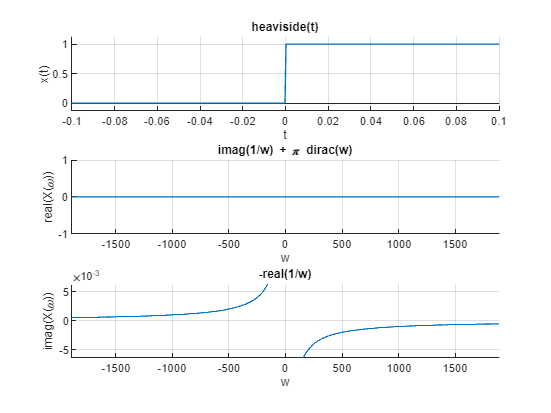

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = heaviside(t);
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

Impuls prostokątny o amplitudzie 1 i czasie trwania T = 2/f0

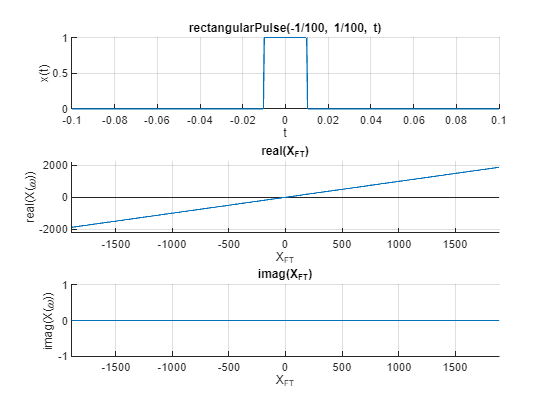

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
T0 = 2/f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = rectangularPulse(-1/f0, 1/f0, t);
FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

Impuls trójkątny o amplitudzie 1 i czasie trwania T = 2/f0

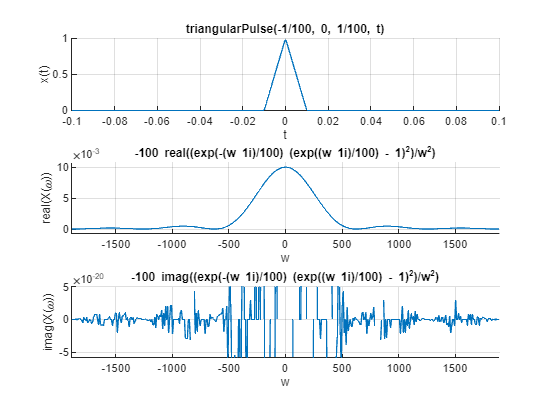

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
T0 = 2/f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = triangularPulse(-1/f0, 1/f0, t);
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

### Zadanie 3

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
T0 = 2/f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = (1 + 0.5*sin(w0/10*t))*cos(w0*t);
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

### ZD2

clear all;
close all;
syms T0 f0 w0 t
f0 = 100; %Hz
w0 = 2*pi*f0;
m = [0.0 0.2 0.5 0.6 0.8 1.0];
power = 1:6;
T0 = 1/f0;
% sygnal modulowany
x = (1 + 0.5*sin(w0/10*t))*cos(w0*t);
%sygnał nośny
xn = cos(w0*t);
for i = 1:6
 power(i) = double(f0*int((1+m(i)*xn)*cos(w0*T0)*(1+m(i)*xn)*cos(w0*t),t,[-T0*5 T0*5])/10);
end
moc05 = double(f0*int((x*x),t,[-T0*5 T0*5])/10)

moc05 = 0.5625

% Moc sygnału nośnego
P_xn = f0 * int(xn^2, t, [0, 1/f0])

$$P\_xn = \frac{1}{2}$$

% Moc sygnału modulowanego
P_x = f0 / 10 * int(x^2, t, [0, 10/f0])

$$P\_x = \frac{9}{16}$$

Moc jest wprost proporcjonalna do współczynnika modulacji.

### Zadanie 4

Impuls prostokątny    

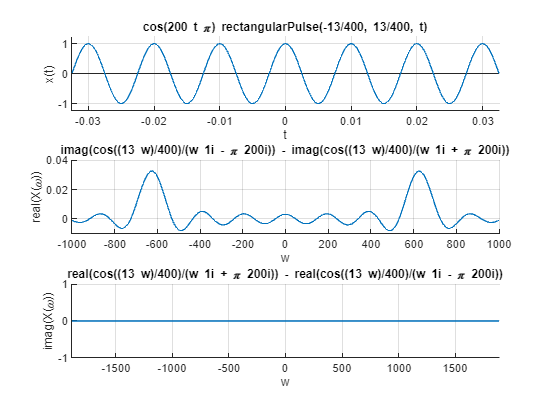

clear all; close all;
syms okno c T0 t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-6.5/(2*f0);6.5/(2*f0)];
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = cos(w0*t);
T0 = 6.5/f0;
c = T0/2;
okno = rectangularPulse(-T0/2, T0/2, t); 
x = x*okno;
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.01 0.04])
xlim([-1000 1000])
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

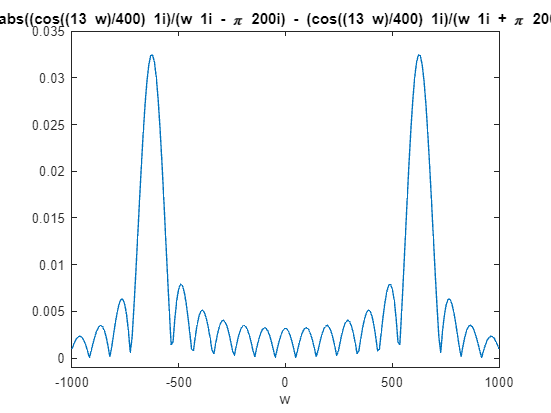

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
A = abs(X_FT);
figure
ezplot(A, BND_w);
xlim([-1000 1000]);
ylim([-0.001, 0.035]);

Impuls trójkątny

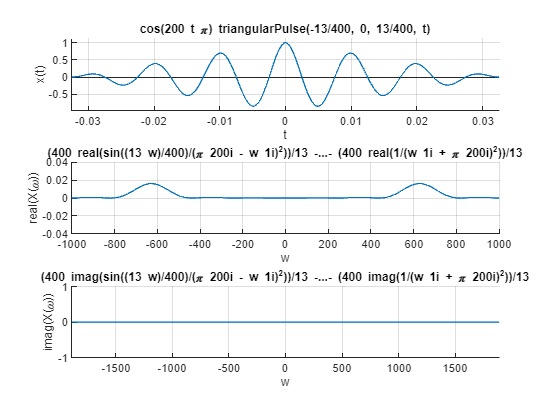

clear all; close all;
syms okno c T0 t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-6.5/(2*f0);6.5/(2*f0)];
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = cos(w0*t);
T0 = 6.5/f0;
c = T0/2;
okno =triangularPulse(-T0/2, T0/2, t);
x = x*okno;
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.04 0.04])
xlim([-1000 1000])
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

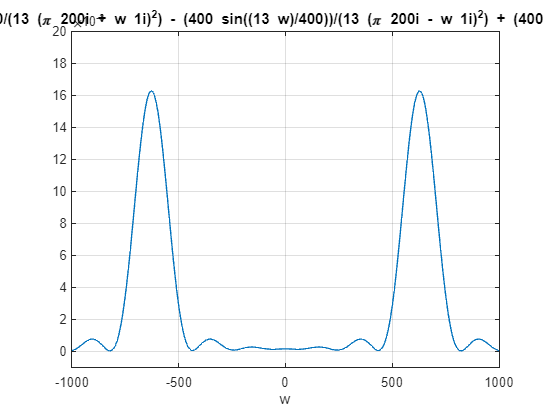

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
A = abs(X_FT);
figure
ezplot(A, BND_w);
xlim([-1000 1000]);
ylim([-0.001, 0.020]);
grid on

Krzywa Gaussa

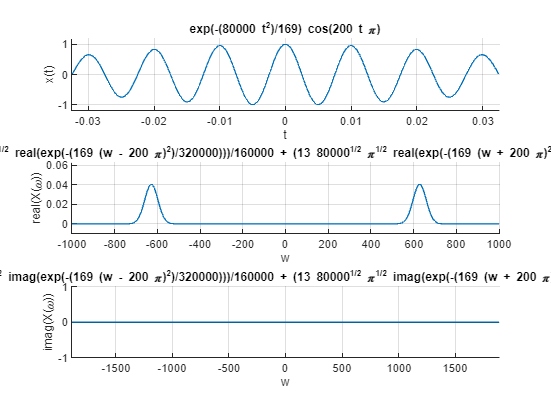

clear all; close all;
syms okno c T0 t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-6.5/(2*f0);6.5/(2*f0)];
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];
x = cos(w0*t);
T0 = 6.5/f0;
c = T0/2;
okno = exp(-t.^2/(2*c.^2));
x = x*okno;
X_FT = fourier(x);
figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
ylim([-0.01 2*pi*0.01])
xlim([-1000 1000])
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

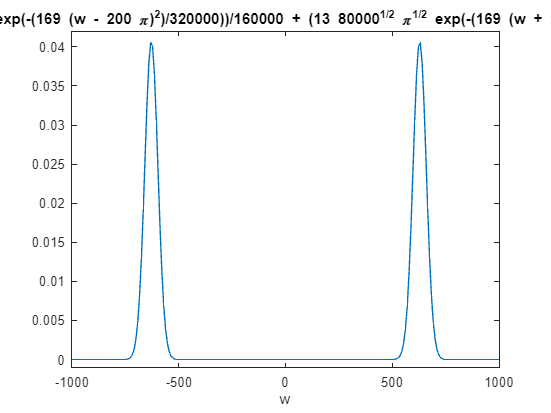

A = abs(X_FT);
figure
ezplot(A, BND_w);
xlim([-1000 1000]);
ylim([-0.001, 0.042]);